- Make a plot of the first derivative estimate from finite differences.

- Make a plot of the 2nd and 3rd derivatives estimated from finite differences.

- What is the amount of noise (measured by standard deviation) to get all 3 derivatives accurate to within 10% of the true (analytic) value?

% ------------------------------------------------------
A     = 1.1; % fluorescence intensity units
omega = 2.6; % rad/s
A_0   = 0.01;

u=@(t) A*sin(omega*t)+A_0;

tArray = linspace(0,1.6,200);
uArray = u(tArray); % an array of samples of u
% ------------------------------------------------------

% analytical solutions (in real life, we might not know these)
dudtExact      =  A*omega*cos(omega*tArray);
du2dt2Exact    = -A*omega^2*sin(omega*tArray);
du3dt3Exact    = -A*omega^3*cos(omega*tArray);

% Take the sample and add a bit of noise
 uObserved = u(tArray) + (0)*randn(size(tArray));
 
display(uObserved);

uObserved =     0.0100    0.0330    0.0560    0.0789    0.1019    0.1248    0.1476    0.1704    0.1931    0.2157    0.2383    0.2607    0.2831    0.3053    0.3274    0.3493    0.3711    0.3927    0.4142    0.4355    0.4566    0.4775    0.4982    0.5187    0.5390    0.5591    0.5789    0.5984    0.6177    0.6368    0.6555    0.6740    0.6922    0.7101    0.7276    0.7449    0.7619    0.7785    0.7948    0.8107    0.8263    0.8415    0.8564    0.8709    0.8850    0.8988    0.9121    0.9251    0.9376    0.9498



dudt = diff(uObserved)./diff(tArray) %10-6

dudt =     2.8598    2.8585    2.8560    2.8523    2.8473    2.8411    2.8336    2.8249    2.8149    2.8037    2.7913    2.7777    2.7629    2.7468    2.7296    2.7111    2.6915    2.6707    2.6487    2.6256    2.6013    2.5759    2.5494    2.5217    2.4930    2.4631    2.4322    2.4002    2.3672    2.3331    2.2981    2.2620    2.2249    2.1869    2.1478    2.1079    2.0670    2.0253    1.9826    1.9391    1.8947    1.8495    1.8035    1.7568    1.7092    1.6609    1.6119    1.5621    1.5117    1.4606


dudt2 = diff(dudt)./diff(tArray(1:end-1)) %10^-4

dudt2 =    -0.1554   -0.3108   -0.4660   -0.6210   -0.7758   -0.9302   -1.0842   -1.2377   -1.3907   -1.5431   -1.6948   -1.8458   -1.9959   -2.1452   -2.2936   -2.4409   -2.5872   -2.7324   -2.8763   -3.0190   -3.1604   -3.3004   -3.4390   -3.5760   -3.7115   -3.8454   -3.9776   -4.1080   -4.2367   -4.3635   -4.4884   -4.6113   -4.7323   -4.8511   -4.9678   -5.0824   -5.1948   -5.3048   -5.4126   -5.5180   -5.6209   -5.7215   -5.8195   -5.9150   -6.0079   -6.0981   -6.1857   -6.2706   -6.3528   -6.4322


dudt3 = diff(dudt2)./diff(tArray(1:end-2)) %0

dudt3 =   -19.3230  -19.3061  -19.2808  -19.2471  -19.2049  -19.1543  -19.0954  -19.0282  -18.9526  -18.8687  -18.7766  -18.6763  -18.5678  -18.4512  -18.3265  -18.1939  -18.0533  -17.9048  -17.7484  -17.5843  -17.4126  -17.2332  -17.0463  -16.8519  -16.6502  -16.4412  -16.2250  -16.0018  -15.7715  -15.5344  -15.2904  -15.0398  -14.7826  -14.5189  -14.2489  -13.9727  -13.6904  -13.4021  -13.1079  -12.8080  -12.5025  -12.1915  -11.8752  -11.5538  -11.2272  -10.8958  -10.5596  -10.2188   -9.8735   -9.5239


%plot of first derivative form finite differences
du1 = abs(dudt-dudtExact(1:end-1))./dudtExact(1:end-1)

du1 =     0.0001    0.0003    0.0005    0.0007    0.0009    0.0012    0.0014    0.0016    0.0018    0.0021    0.0023    0.0025    0.0028    0.0030    0.0032    0.0035    0.0037    0.0040    0.0042    0.0045    0.0047    0.0050    0.0052    0.0055    0.0058    0.0061    0.0064    0.0067    0.0070    0.0073    0.0076    0.0080    0.0083    0.0087    0.0091    0.0095    0.0099    0.0103    0.0107    0.0112    0.0116    0.0121    0.0127    0.0132    0.0138    0.0144    0.0151    0.0157    0.0165    0.0173


%en estimate -true value / true value
du2 = abs(du2dt2-du2dt2Exact(1:end-2))./du2dt2Exact(1:end-2)

du2 =       -Inf   -1.0256   -0.4971   -0.3308   -0.2507   -0.2009   -0.1622   -0.1427   -0.1241   -0.1066   -0.1031   -0.0863   -0.0818   -0.0749   -0.0681   -0.0649   -0.0587   -0.0582   -0.0521   -0.0477   -0.0483   -0.0448   -0.0419   -0.0388   -0.0382   -0.0360   -0.0347   -0.0323   -0.0316   -0.0305   -0.0279   -0.0274   -0.0262   -0.0251   -0.0240   -0.0241   -0.0204   -0.0214   -0.0214   -0.0182   -0.0193   -0.0178   -0.0169   -0.0169   -0.0148   -0.0149   -0.0151   -0.0133   -0.0132   -0.0121


du3 = abs(du3dt3 - du3dt3Exact(1:end-3))./du3dt3Exact(1:end-3)

du3 =    -0.0573   -0.0320   -0.0027   -0.0093   -0.0000   -0.0332   -0.0230   -0.0088   -0.0361   -0.0682   -0.0857   -0.0286   -0.0125   -0.0266   -0.0161   -0.0416   -0.0462   -0.0604   -0.0399   -0.0567   -0.0356   -0.0294   -0.0400   -0.0180   -0.0281   -0.0058   -0.0452   -0.0031   -0.0114   -0.0651   -0.0018   -0.0258   -0.0244   -0.0289   -0.0187   -0.1489   -0.0585   -0.0125   -0.1506   -0.0662   -0.0766   -0.0426   -0.0014   -0.1229   -0.0079   -0.0139   -0.1262   -0.0087   -0.0904   -0.0153


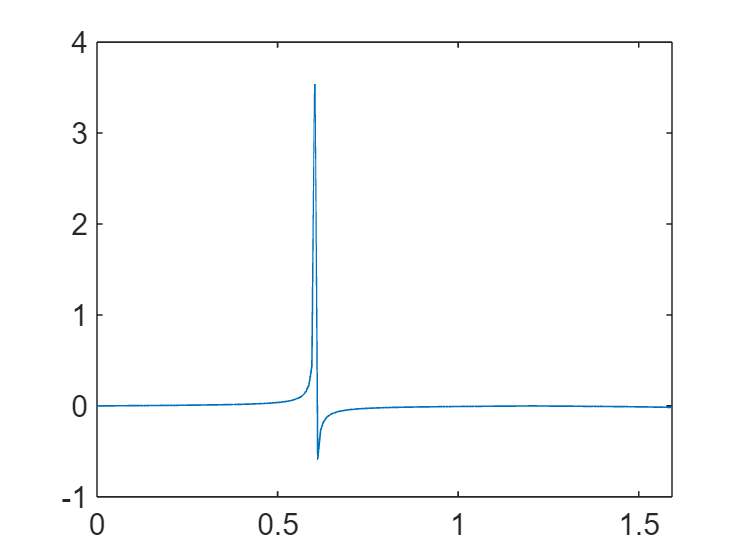


plot(tArray(1:end-1), du1)

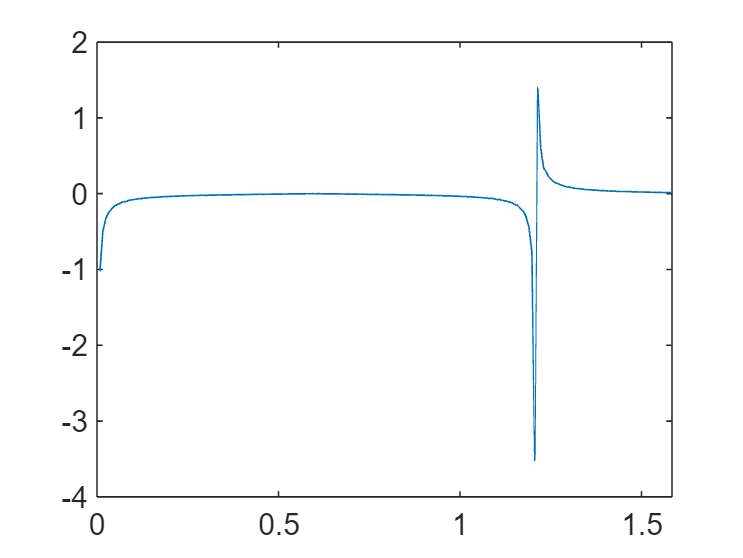

plot(tArray(1:end-2), du2)

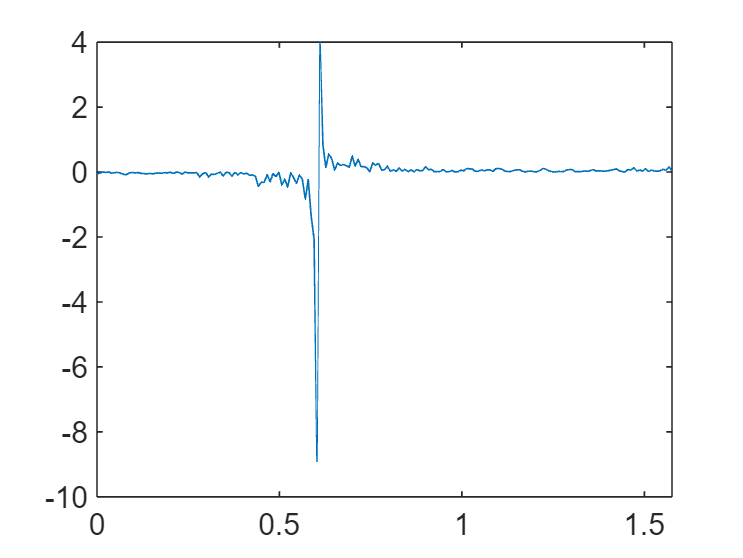

plot(tArray(1:end-3), du3)

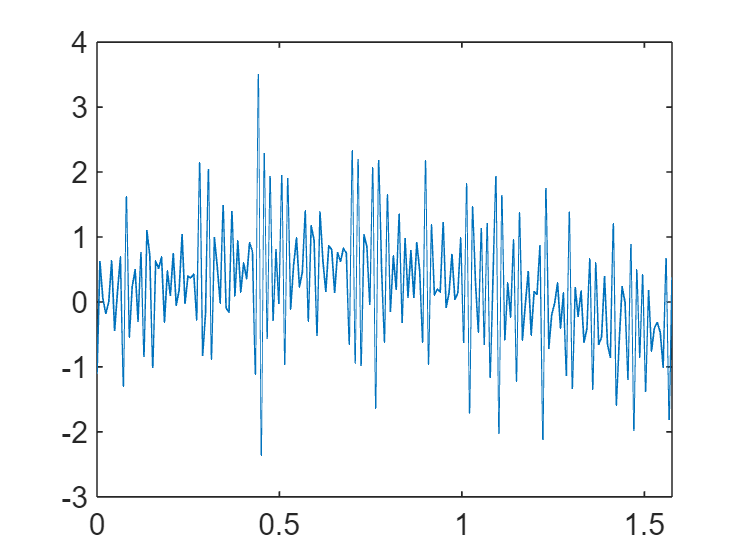

plot(tArray(1:end-3), du3dt3 - du3dt3Exact(1:end-3))